# Hurricane Harvey Analysis

### Table of Contents

- Import the Data

- States Impacted by harvey

- Dates that Hurricane Harvey happened in between

- Two States Most Impacted by Harvey

- Table of Events for Two Most Impacted States

- Figure of Event Types

- Figure of Event Locations

- Three Counties with Most Events in Arkansas

- Three Counties with Most Events in Kentucky

- Three Counties with Highest Property Cost in Arkansas

- Three Counties with Highest Property Cost in Kentucky

- Recommendations

## Background and Scope

### Import the Data

Imported: 

- State

- Event_Table

- CZ_Name

- Begin_Date_Time

- End_Date_Time

- Property_Cost

- Begin_Lat

- Begin_Lon

- End_Lat

- End_Lon

uiimport("StormEvents\StormEvents_2017_finalProject.csv")

### States Impacted by harvey

    In order to filter the data to know which data is related to hurricane Harvey we need to filter the data to only include these states.

- Arkansas

- Kentucky

- Louisiana

- Mississippi

- North Carolina

- Tennessee

- Texas.

StormEvents2017finalProject = StormEvents2017finalProject(StormEvents2017finalProject.State == 'ARKANSAS' ...
    | StormEvents2017finalProject.State == 'KENTUCKY' | StormEvents2017finalProject.State == 'LOUISIANA' ...
    | StormEvents2017finalProject.State == 'MISSISSIPPI' | StormEvents2017finalProject.State == 'NORTH CAROLINA' ...
    | StormEvents2017finalProject.State == 'TENNESSEE' | StormEvents2017finalProject.State == 'TEXAS', :)

StormEvents2017finalProject = 10667×10 table
        State            Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    _________________    __________    ___________________    ___________________    _____________    _________    _________    _______    _______

    ARKANSAS          Hail                 FRANKLIN      2017-04-26 07:57:00    2017-04-26 07:57:00            0         35.297       -94.038     35.297     -94.038
    TEXAS             Hail                 HENDERSON     2017-05-03 14:06:00    2017-05-03 14:06:00         1000       

### Dates that Hurricane Harvey happened in between

    I will asume that assume that Harvey related events occurred only from the 17th of August to the 3rd of September.

StormEvents2017finalProject = StormEvents2017finalProject(StormEvents2017finalProject.Begin_Date_Time >= datetime('2017-08-17 00:00:00') ...
    & StormEvents2017finalProject.End_Date_Time <= datetime('2017-09-04 00:00:00') ...
    | ismissing(StormEvents2017finalProject.Begin_Date_Time), :);

    At the end we will get the following table

StormEvents2017finalProject

StormEvents2017finalProject = 573×10 table
        State            Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    _________________    ___________    ___________________    ___________________    _____________    _________    _________    _______    _______

    TEXAS             Tropical Storm       MONTGOMERY     2017-08-25 12:00:00    2017-08-30 00:00:00         7e+09           NaN           NaN        NaN         NaN
    MISSISSIPPI       Strong Wind          LOWNDES        2017-09-01 01:00:00    2017-09-01 01:00:00          5000    

### Two States Most Impacted by Harvey

    Here we will find the two most states that have the heighest property cost

T = groupsummary(StormEvents2017finalProject, 'State', 'sum', 'Property_Cost'); % finding the total property cost by state
T.sum_Property_Cost = sort(T.sum_Property_Cost, 'descend') % sort the rows in a descending order according to the sum_Property_Cost coloumn

T = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    ARKANSAS              52           7.7427e+10    
    KENTUCKY              20           7.5277e+07    
    LOUISIANA             85           1.2339e+07    
    MISSISSIPPI           39             9.15e+05    
    NORTH CAROLINA        59             5.04e+05    
    TENNESSEE             46             4.35e+05    
    TEXAS                272                61000    


T([1, 2], :) % display the first two rows

ans = 2×3 table
     State      GroupCount    sum_Property_Cost
    ________    __________    _________________

    ARKANSAS        52           7.7427e+10    
    KENTUCKY        20           7.5277e+07    


    From here we can see that the two most impacted states are Arkansas and Kentucky.

### Table of Events for Two Most Impacted States

    Here we will create a table with only the rows which contains the states Arknasas and Kentucky and group them with the events most frequent

clearvars -except StormEvents2017finalProject % delete the variables T and ans
T = StormEvents2017finalProject(StormEvents2017finalProject.State == "ARKANSAS" ...
    | StormEvents2017finalProject.State == 'KENTUCKY', :);
T = groupsummary(T, "Event_Type");
T.GroupCount = sort(T.GroupCount, 'descend'); 
T

T = 7×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood              24    
    Flood                    19    
    Hail                     16    
    Heat                      9    
    Strong Wind               2    
    Thunderstorm Wind         1    
    Tornado                   1    


clear T

    From the table above we can see that the events that impactes these states from most frequent to least frequent are:

- Flash Flood

- Flood

- Hail

- Heat

- Strong Wind

- Thunderstorm Wind

- Tornado

## Visualizations

### Figure of Event Types

    First we will show a visualization for the event type and number of occurancies of events that occured in Arkansas and Kentucky.

#### Arkansas and Kentucky

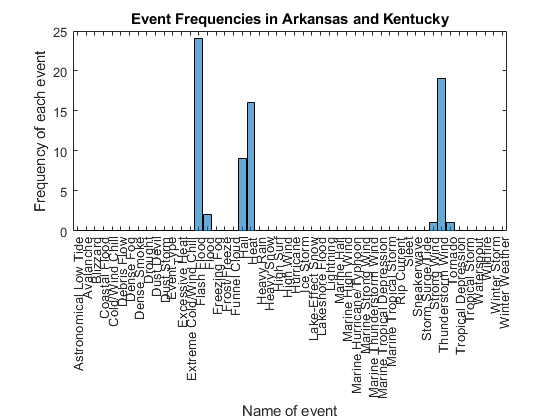

T = StormEvents2017finalProject(StormEvents2017finalProject.State == "ARKANSAS" ...
    | StormEvents2017finalProject.State == 'KENTUCKY', :);
histogram(T.Event_Type)

title('Event Frequencies in Arkansas and Kentucky')
xlabel('Name of event')
ylabel('Frequency of each event')

Showing a table of frequencies to better interpret the data

T = groupsummary(T, 'Event_Type');
T.GroupCount = sort(T.GroupCount, 'descend');
T

T = 7×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood              24    
    Flood                    19    
    Hail                     16    
    Heat                      9    
    Strong Wind               2    
    Thunderstorm Wind         1    
    Tornado                   1    


#### Arkansas

Arkansas Histogram to show the frequencies

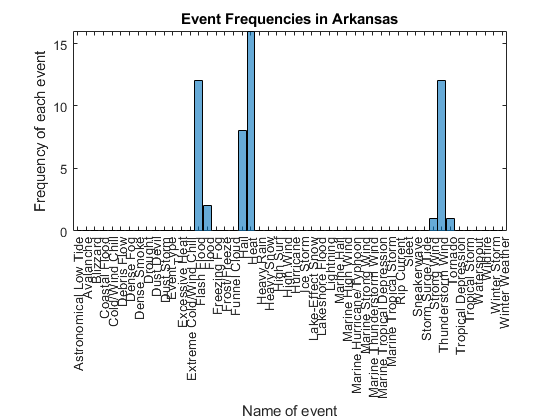

clear T
T = StormEvents2017finalProject(StormEvents2017finalProject.State == "ARKANSAS", :);
histogram(T.Event_Type)

title('Event Frequencies in Arkansas')
xlabel('Name of event')
ylabel('Frequency of each event')

Showing a table of frequencies to better interpret the data

T = groupsummary(T, 'Event_Type');
T.GroupCount = sort(T.GroupCount, 'descend');
T

T = 7×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood              16    
    Flood                    12    
    Hail                     12    
    Heat                      8    
    Strong Wind               2    
    Thunderstorm Wind         1    
    Tornado                   1    


#### Kentucky

Kentucky Histogram to show the frequencies

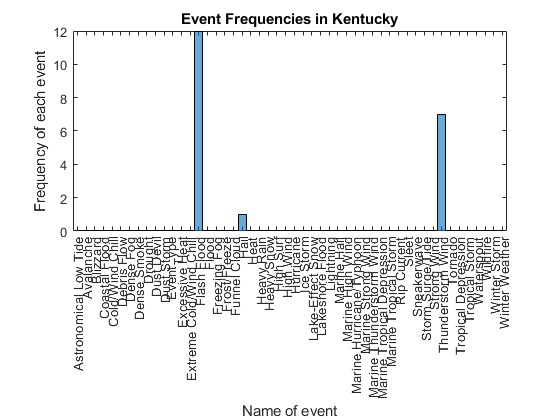

clear T
T = StormEvents2017finalProject(StormEvents2017finalProject.State == "KENTUCKY", :);
histogram(T.Event_Type)

title('Event Frequencies in Kentucky')
xlabel('Name of event')
ylabel('Frequency of each event')

Showing a table of frequencies to better interpret the data

T = groupsummary(T, 'Event_Type');
T.GroupCount = sort(T.GroupCount, 'descend');
T

T = 3×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood              12    
    Hail                      7    
    Thunderstorm Wind         1    


clear T

### Figure of Event Locations

T = StormEvents2017finalProject(StormEvents2017finalProject.State == "ARKANSAS" ...
    | StormEvents2017finalProject.State == 'KENTUCKY', :);
T = T(~isnan(T.Begin_Lat), :);
T = T(~isnan(T.Begin_Lon), :);
T = T(~isnan(T.End_Lat), :);
T = T(~isnan(T.End_Lon), :);

To calculate the are of each marker I will use a calculation in one of the examples in the [documentation](https://www.mathworks.com/help/matlab/ref/geoscatter.html)

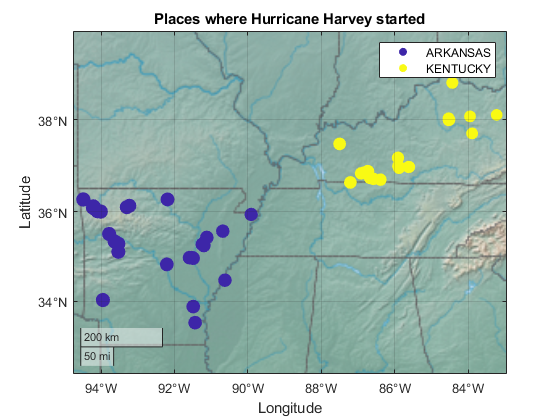

T.A_Begin = 101 + 100*(sind(2*T.Begin_Lon));
T.A_End = 101 + 100*(sind(2*T.End_Lon));

ARKANSAS = T(T.State == "ARKANSAS", :);
KENTUCKY = T(T.State == "KENTUCKY", :);

clear T

geoscatter(ARKANSAS.Begin_Lat,ARKANSAS.Begin_Lon, ARKANSAS.A_Begin, ARKANSAS.State, 'filled')
hold on
geoscatter(KENTUCKY.Begin_Lat,KENTUCKY.Begin_Lon, KENTUCKY.A_Begin, KENTUCKY.State, 'filled')
hold off
title('Places where Hurricane Harvey started')
legend('ARKANSAS', 'KENTUCKY')
geobasemap colorterrain

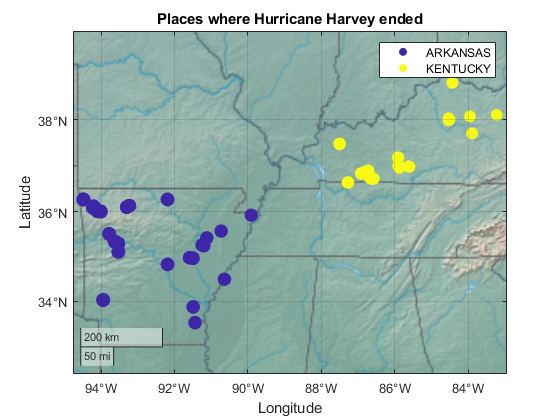

geoscatter(ARKANSAS.End_Lat,ARKANSAS.End_Lon, ARKANSAS.A_End, ARKANSAS.State, 'filled')
hold on
geoscatter(KENTUCKY.End_Lat,KENTUCKY.End_Lon, KENTUCKY.A_End, KENTUCKY.State, 'filled')
hold off
title('Places where Hurricane Harvey ended')
legend('ARKANSAS', 'KENTUCKY')
geobasemap colorterrain

clear KENTUCKY
clear ARKANSAS

## Analysis

### Three Counties with Most Events in Arkansas

#### Table of the Three Counties with Most Events

T = StormEvents2017finalProject(StormEvents2017finalProject.State == 'ARKANSAS', :);
T = groupsummary(T, 'CZ_Name');
T.GroupCount = sort(T.GroupCount, 'descend')

T = 32×2 table
     CZ_Name      GroupCount
    __________    __________

    ASHLEY            11    
    BAXTER             4    
    BENTON             3    
    BOONE              3    
    CHICOT             2    
    COLUMBIA           2    
    CRAIGHEAD          2    
    CRITTENDEN         1    
    CROSS              1    
    DESHA              1    
    FRANKLIN           1    
    HEMPSTEAD          1    
    HOWARD             1    
    JACKSON            1    
    LAFAYETTE          1    
    LEE                1    


T = T([1, 2, 3], :);
T

T = 3×2 table
    CZ_Name    GroupCount
    _______    __________

    ASHLEY         11    
    BAXTER          4    
    BENTON          3    


    The three Counties are:

- Ashley

- Baxter

- Benton

clear T

### Three Counties with Most Events in Kentucky

#### Table of the Three Counties with Most Events

T = StormEvents2017finalProject(StormEvents2017finalProject.State == 'KENTUCKY', :);
T = groupsummary(T, 'CZ_Name');
T.GroupCount = sort(T.GroupCount, 'descend')

T = 12×2 table
     CZ_Name      GroupCount
    __________    __________

    BARREN            3     
    ELLIOTT           3     
    ESTILL            3     
    FAYETTE           2     
    HART              2     
    LOGAN             1     
    METCALFE          1     
    MONTGOMERY        1     
    PENDLETON         1     
    SIMPSON           1     
    TODD              1     
    WEBSTER           1     


T = T([1, 2, 3], :);
T

T = 3×2 table
    CZ_Name    GroupCount
    _______    __________

    BARREN         3     
    ELLIOTT        3     
    ESTILL         3     


    The three Counties are:

- Barren

- Elliott

- Estill

clear T

### Three Counties with Highest Property Cost in Arkansas

#### Table of the Three Counties with Highest Property Cost

T = StormEvents2017finalProject(StormEvents2017finalProject.State == 'ARKANSAS', :);
T = groupsummary(T, 'CZ_Name', 'sum', 'Property_Cost');
T.sum_Property_Cost = sort(T.sum_Property_Cost, 'descend')

T = 32×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    ASHLEY            1               39000      
    BAXTER            1               15000      
    BENTON            1                5000      
    BOONE             1                2000      
    CHICOT            1                   0      
    COLUMBIA          1                   0      
    CRAIGHEAD         1                   0      
    CRITTENDEN        1                   0      
    CROSS             1                   0      
    DESHA             1                   0      
    FRANKLIN          1                   0      
    HEMPSTEAD         1                   0      
    HOWARD            2                   0      
    JACKSON           1                   0      
    LAFAYETTE         1                   0      
    LEE               1         

T = T([1, 2, 3], :);
T

T = 3×3 table
    CZ_Name    GroupCount    sum_Property_Cost
    _______    __________    _________________

    ASHLEY         1               39000      
    BAXTER         1               15000      
    BENTON         1                5000      


    The three Counties are:

- Ashley

- Baxter

- Benton

clear T

### Three Counties with Highest Property Cost in Kentucky

#### Table of the Three Counties with Highest Property Cost

T = StormEvents2017finalProject(StormEvents2017finalProject.State == 'KENTUCKY', :);
T = groupsummary(T, 'CZ_Name', 'sum', 'Property_Cost');
T.sum_Property_Cost = sort(T.sum_Property_Cost, 'descend')

T = 12×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    BARREN            2              3.5e+05     
    ELLIOTT           1                34000     
    ESTILL            1                20000     
    FAYETTE           3                20000     
    HART              1                10000     
    LOGAN             3                 1000     
    METCALFE          2                    0     
    MONTGOMERY        1                    0     
    PENDLETON         1                    0     
    SIMPSON           3                    0     
    TODD              1                    0     
    WEBSTER           1                    0     


T = T([1, 2, 3], :);
T

T = 3×3 table
    CZ_Name    GroupCount    sum_Property_Cost
    _______    __________    _________________

    BARREN         2              3.5e+05     
    ELLIOTT        1                34000     
    ESTILL         1                20000     


    The three Counties are:

- Barren

- Elliott

- Estill

clear T

## Conclusions and Recommendations

### Recommendations

    If the people effected by the hurricane agreed to go to a different state then they should be sent to any state not in this table.

    If the people did not agree to go to a different state then they should go to any countie not in this table if they are from Arkansas if it existed.

    If the people did not agree to go to a different state then they should go to any countie not in this table if they are from Kentucky if it existed.

clear StormEvents2017finalProject